%【2-1】
% 支路电流法
%   1  3  4  5  6 u 
clc;
A=[ -1 0  1  0  1 0
    0  1  0  1 -1 0
    0  0  1  1  0 0
    1  0  2  0  0 -1
    0  0  0  2  0 -1
    0  0 -2  2  0 0];
b = [0
    0
    20
    -110
    -120
    110];
I = (A\b)';
Iabcu1 = [I(1) I(2) I(5) I(6)]

Iabcu1 =   120.0000  100.0000  137.5000  195.0000


% 节点电压法
% 由于电路中电压源过多 本题不适用节点电压法
% 节点电压法的方程与支路电流法类似，故答案相同

% 网孔电流法
% a b c u 
A = [4 -1 -2 -1
    -1 3 -2 1
    -2 -2 4 0
    1 -1 0 0];
b = [-90
    100
    110
    20];
Iabcu2 = (A\b)'

Iabcu2 =   120.0000  100.0000  137.5000  195.0000


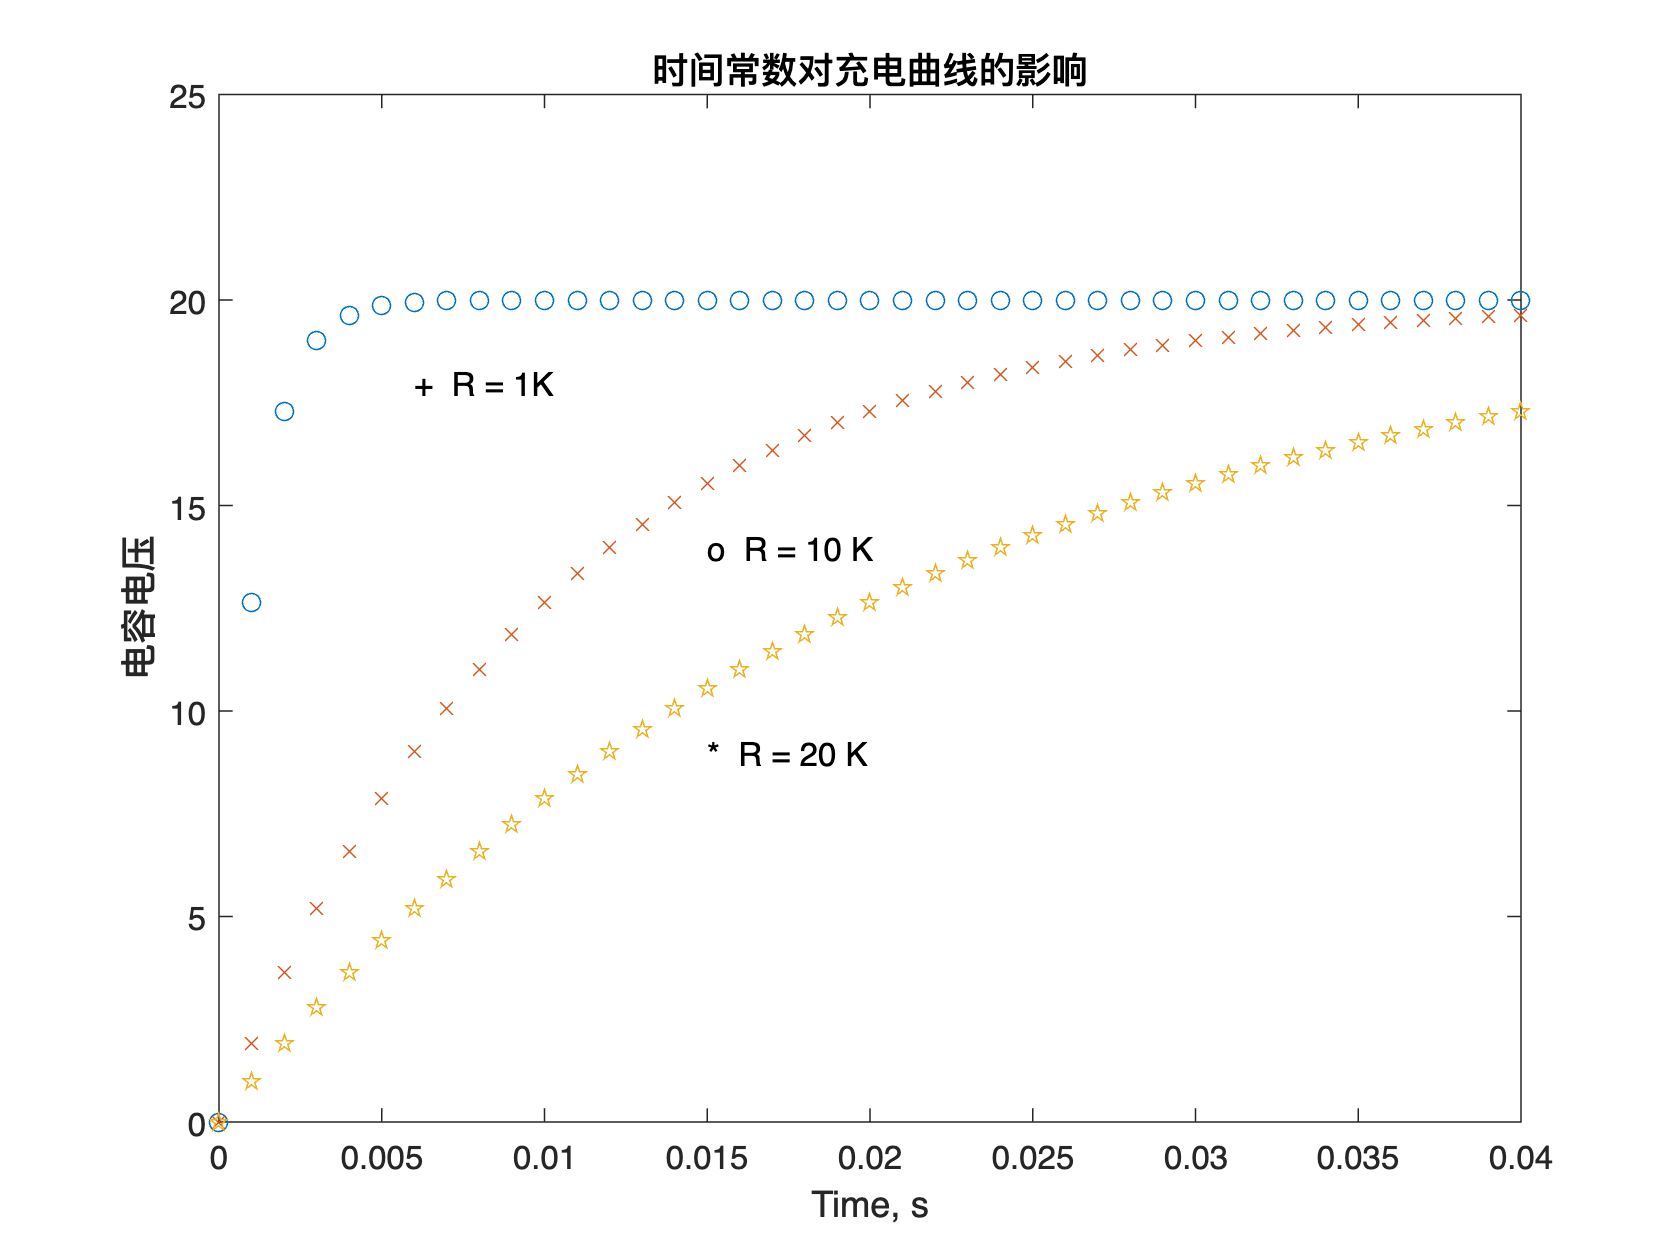

% 【2-2】
clear;
C = 1e-6;
R=[1e3, 10e3, 20e3];
tau=R*C;
t = 0:0.001:0.04;             
for k=1:3
    uc(k,:)=20*(1-exp(-t/tau(k)));                                                          
end
plot(t,uc(1,:),'o',t,uc(2,:),'x', t,uc(3,:),'p')    
axis([0 0.04 0 25])            
title('时间常数对充电曲线的影响(方法一)')
xlabel('Time, s')
ylabel('电容电压')
text(0.006, 18.0, '+  R = 1K')
text(0.015, 14.0, 'o  R = 10 K ')
text(0.015, 9.0, '*  R = 20 K')

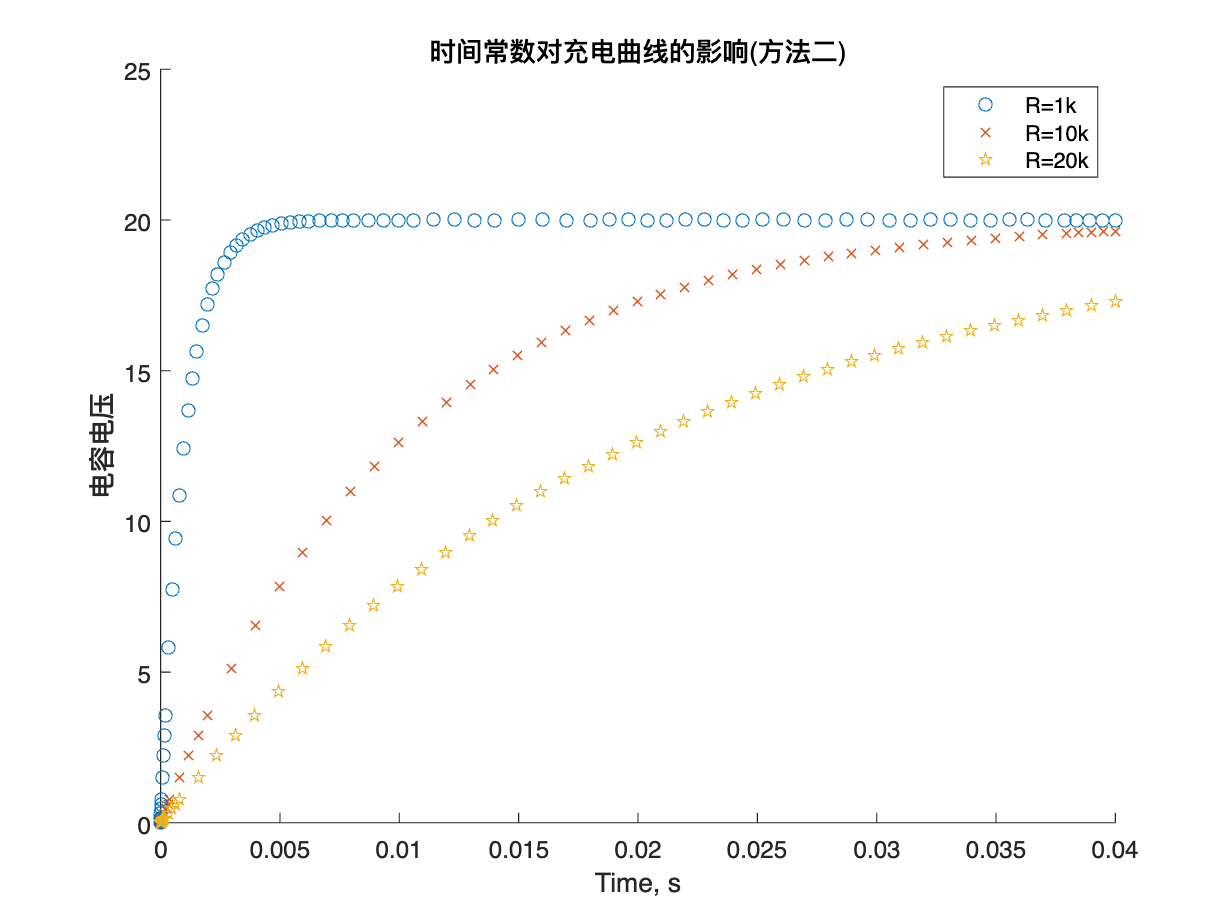

clear;
figure;
tspan=[0,0.04]; %横轴t区间
y0=0;      %初始值为0
[t1,YY1]=ode45('DYDtR1',tspan,y0); %用ode45函数求解微分方程
[t2,YY2]=ode45('DYDtR2',tspan,y0); %用ode45函数求解微分方程
[t3,YY3]=ode45('DYDtR3',tspan,y0); %用ode45函数求解微分方程
hold on;
plot(t1,YY1(:,1),'o')
plot(t2,YY2(:,1),'x')
plot(t3,YY3(:,1),'p')    
hold off;
title('时间常数对充电曲线的影响(方法二)')
xlabel('Time, s')
ylabel('电容电压')
legend("R=1k","R=10k","R=20k")

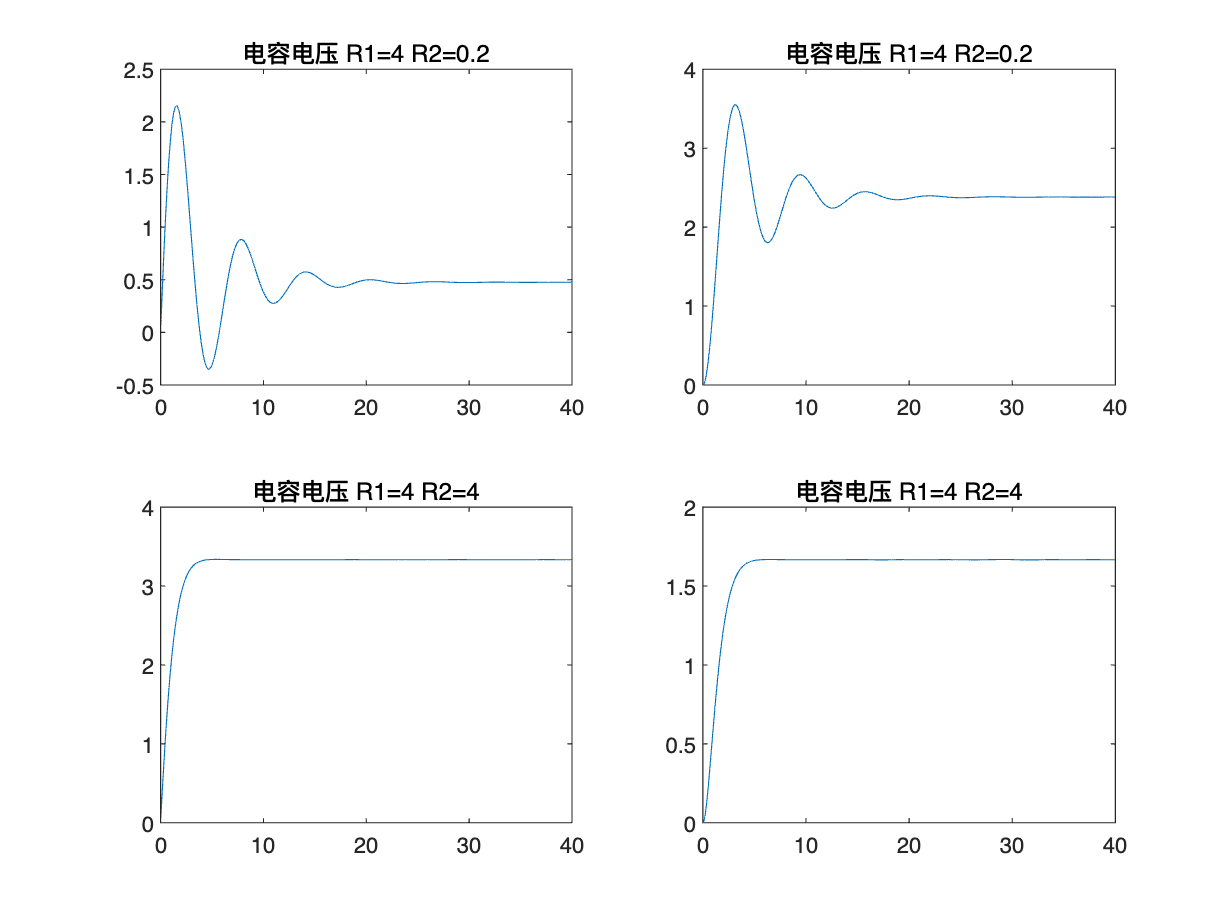

tspan=[0,40];
y0=[0;0];
[t,YY]=ode45('Tworank',tspan,y0);
subplot(2,2,1),plot(t,YY(:,1)),
title('电容电压 R1=4 R2=0.2');
subplot(2,2,2),plot(t,YY(:,2)),
title('电容电压 R1=4 R2=0.2');
tspan=[0,40];
y0=[0;0];
[t,YY]=ode45('Tworank2',tspan,y0);
subplot(2,2,3),plot(t,YY(:,1)),
title('电容电压 R1=4 R2=4');
subplot(2,2,4),plot(t,YY(:,2)),
title('电容电压 R1=4 R2=4');

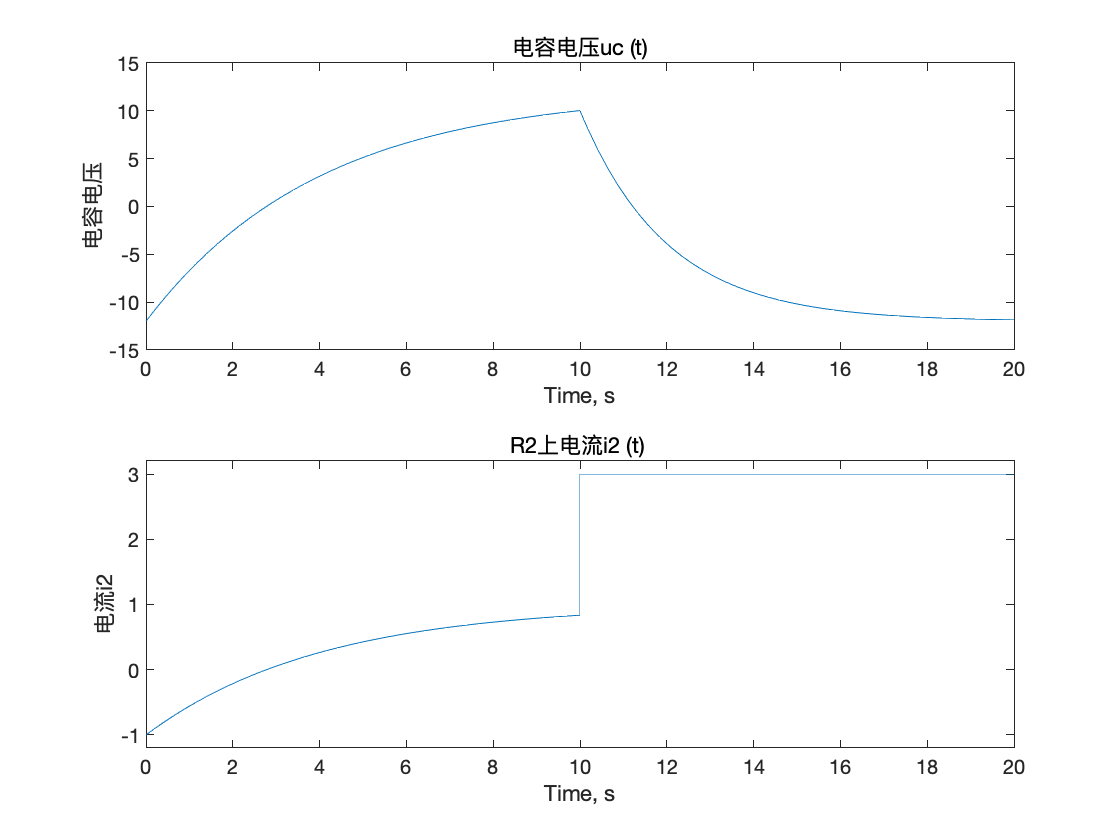

% 【思考题2.7】ode函数求解常系数线性微分方程
clear;
tspan = [0,10];   % 横轴t区间
u0 = -12;         % 初始值为0
[t1,ut1] = ode45('fq271m1',tspan,u0); 
u0 = ut1(end);
[t2,ut2] = ode45('fq272m1',tspan,u0);
tAll = cat(1, t1, t2+10);
utAll = cat(1, ut1, ut2);
subplot(2,1,1)
plot(tAll,utAll);
xlabel('Time, s')
ylabel('电容电压')
title('电容电压uc (t)')
it1 = ut1/12;
it2 = ut2*0+3;
itAll = cat(1, it1, it2);
subplot(2,1,2)
plot(tAll,itAll);
ylim([-1.2 3.2])
title('R2上电流i2 (t) ')
xlabel('Time, s')
ylabel('电流i2')

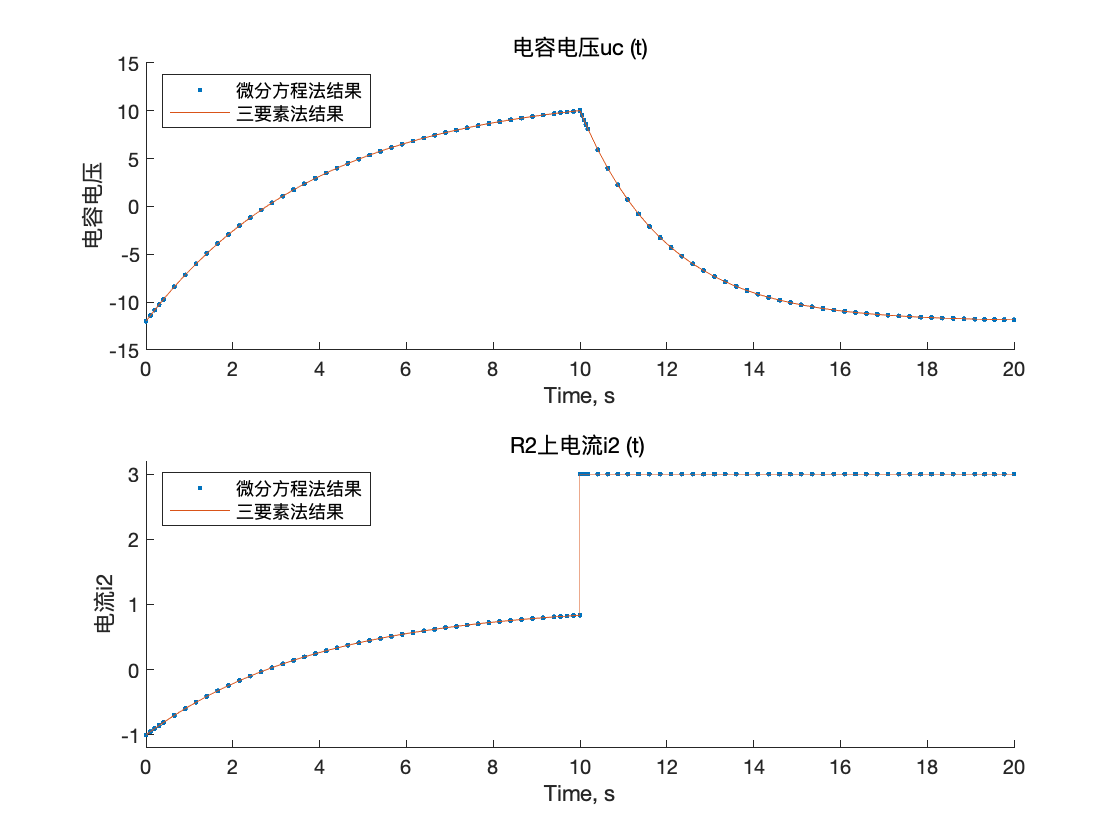

% 【思考题2.7】三要素法
uc1 = -12*exp(-t1/4)+12*(1-exp(-t1/4));
uc2 = uc1(end)*exp(-t2/2)-12*(1-exp(-t2/2));
ucAll = cat(1, uc1, uc2);
figure;
subplot(2,1,1);
hold on;
plot(tAll,utAll,'.');
plot(tAll,ucAll);
hold off;
xlabel('Time, s');
ylabel('电容电压');
title('电容电压uc (t)');
legend("微分方程法结果","三要素法结果",'Location','northwest')
it21 = uc1/12;
it22 = uc2*0+3;
it2All = cat(1, it1, it2);
subplot(2,1,2)
hold on;
plot(tAll,itAll,'.');
plot(tAll,it2All);
hold off;
ylim([-1.2 3.2])
title('R2上电流i2 (t) ')
xlabel('Time, s')
ylabel('电流i2')
legend("微分方程法结果","三要素法结果",'Location','northwest')